# Example of Reproductive Ratio Calculation at the Netherlands trap site

In this example MATLAB live script we demonstrate the climate data and the BTV risk measurement calculations that were calculated for each E-OBS spatial grid square within, and local to, the European Union. For clarity, we have selected the spatial grid square that contained the trap locations in the Netherlands. In this live script we investigate for this spatial grid:

- The climate data used to calculate BTV risk estimates.

- The estimated biting per cattle, and the range of predictions over unknown variation in quality of local habitat for midges.

- The vectorial capacity per biting midge and per cattle.

- Reproductive ratio estimates for BTV if both cattle and sheep are available to be bitten.

- The proportion of herds that we estimate could have a BTV outbreak if an infectious animal arrived on any given day.

 Each of these items of data and BTV risk estimates are plotted for each day since 1st Jan 2000.

## Climate Data

Daily mean temperature and average rainfall over last week climate variables have already been gathered from the E-OBS climate dataset (see `/data_conversion `folder for scripts).

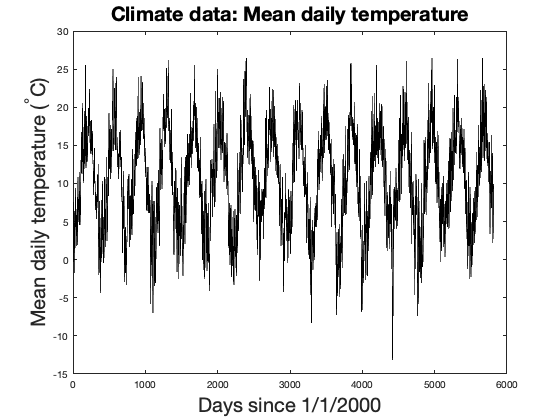

%Load climate data sets 2000-2015
load('temp_at_trap_siteNLDS.mat');
load('rain_at_trap_siteNLDS.mat');

plot(temp_at_trapsite_NLDS,'color','black')
title('Climate data: Mean daily temperature','FontSize',20)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('Mean daily temperature (^\circC)','FontSize',20)

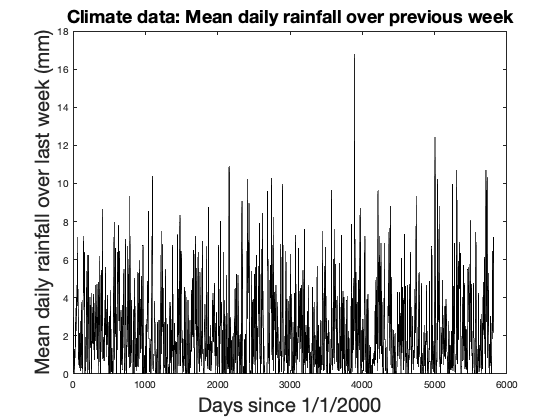

plot(rain_at_trapsite_NLDS,'color','black')
title('Climate data: Mean daily rainfall over previous week','FontSize',18)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('Mean daily rainfall over last week (mm)','FontSize',20)

## Vectorial capacity per midge

First, we convert the temperature timeseries into a daily prediction of the vectorial capacity per midge. This quantity measures the expected number of livestock infected by a **single** midge arriving to bite an infectious animal on each day $t$. We calculate the capacity per vector $\widehat{C}$, which depends on the daily temperatures $\mathcal{T}_t, \mathcal{T}_{t+1},\mathcal{T}_{t+2},...$, using a mathematical formula, 


$${\widehat{C}}(t | \mathcal{T}_t, \mathcal{T}_{t+1}, \ldots) \; = \; V \sum_{\tau=t+1}^{\infty} P_{\alpha}(  \tau ) S_\mu( t,\tau  ) T_\sigma( t,\tau ).$$


Here, $V$ is the vector competence of midges transmitting BTV serotype 8 (the product of the transmission probability from host to vector and vector to host), $P_\alpha(\tau)$ is the temperature dependent probability that the midge bites on day $\tau$, $S_\mu(t,\tau)$ is the temperature dependent probabiltiy that a midge survives between day $t$ and day $\tau$, and $T_\sigma(t,\tau)$ is the temperature dependent probability that a midge infected with BTV on day $t$ has completed its EIP (the period during which although *infected* with BTV the midge is not yet *infectious*). We assumed that the EIP at constant temperature has a 10-stage Erlang distribution. 

Intuitively, $\widehat{C}$ measures the expected number of bites a midge will make in the rest of her life-time with each bite being weighted by the probability it *actually* causes transmission. This was implemented using the function `VC_per_biting_vector_array`:

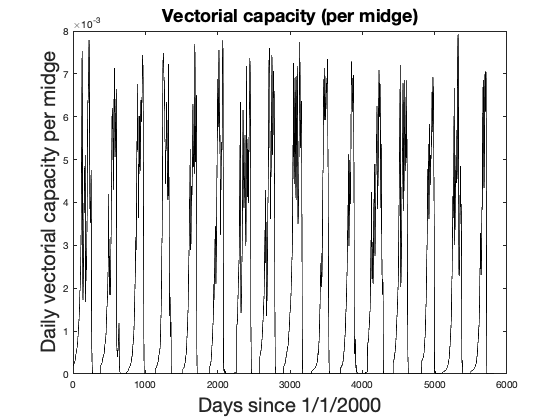

C_hat = VC_per_biting_vector_array(0.1,temp_at_trapsite_NLDS,...
    length(temp_at_trapsite_NLDS));
plot(C_hat,'color','black')
title('Vectorial capacity (per midge)',"FontSize",18)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('Daily vectorial capacity per midge','FontSize',20)

Note that $\widehat{C}$ is a small quantity ($\sim\mathcal{O}(10^{-3})$), which indicates that any single midge is a poor vector of BTV. BTV transmission is sustained by large numbers of bites on infectious livestock over several days. However, $\widehat{C}$ is important because it is used as input for the other functions (e.g the reproductive ratio estimate below), this saves computation power compared to (effectively) recalculating $\widehat{C}$ for each epidemiological quantity of interest.

## Vectorial capacity per livestock

The vectorial capacity of an infected livestock measures the number the expected **future **number of secondary infections amongst livestock due to midge biting per day $t$, which we denote $C$. In this paper, we derived a model for the number of midges biting an animal per day ($B(t)$) given the relevant climatic variables using both midge catch data and comparison to livestock serological data (maximum bites per day were capped at 5000). However, we found that location specific random effects were a significant factor in midge biting; that is that there was intrinsic unexplained difference in the rate of midge biting activity from place to place. For the wider spatial analysis we used the `create_biting_array_from_background_midge_population` function, which is suitable for the multi-dimensional arrays of the pan-European climate dataset. For this example we use `create_biting_vector_from_background_midge_population`, which gives the **median** prediction of midge biting **over possible underlying location-specific random effects**; the random effects we assume vary over time, such as the overdispersion effect, are **averaged** over. In calculating the median biting predictions we use a scaling factor $\xi = 0.51$, as derived in the main paper, and assume a wind velocity of 2.66 m/s (the mean wind velocity over the four nearest weather stations to the Netherlands trap site). The median biting predictions be converted into other percentiles using the `BitingForEachLevelOfP` function (background shading in plot below gives 5th-95th percentile prediction intervals). The `BitingForEachLevelOfP `function takes the median biting predicition and outputs a rescaled daily biting preditions where for each day the median biting rate per cattle (over location-specific random effects) is rescaled to become the *p*th percentile biting rate for that day.

In the main paper, as exemplars, we consider "high", "median" and "low" risk herds as those at, respectively, 95th, 50th, 5th percentiles of midge biting rate. We plot this spread for daily biting at the Netherlands trap site.

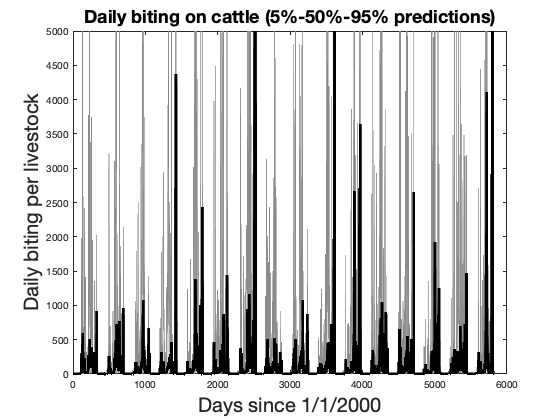

DN = datenum([1999,12,31]) + (1:length(temp_at_trapsite_NLDS));%Days in MATLAB datenum format
B_median = create_biting_vector_from_background_midge_population(0.51,2.66,...
    temp_at_trapsite_NLDS,rain_at_trapsite_NLDS,DN,53);
B_low =  BitingForEachLevelOfP(B_median,temp_at_trapsite_NLDS,2.66,0.05);%5th percentile
B_high =  BitingForEachLevelOfP(B_median,temp_at_trapsite_NLDS,2.66,0.95);%95th percentile
shadedErrorBar(1:length(temp_at_trapsite_NLDS),B_median,[(B_high-B_median)';...
    (B_median - B_low)' ],{'Color','black','LineWidth',3},0.2)
title(['Daily biting on cattle (5%-50%-95% predictions)'],'FontSize',18)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('Daily biting per livestock','FontSize',20);

Having calculated $\widehat{C}$, and $B$, calculating $C$ is simply a rescaling by the number of midges expected to bite a livestock on that day,


$$C(t) = B(t)\widehat{C}(t)$$


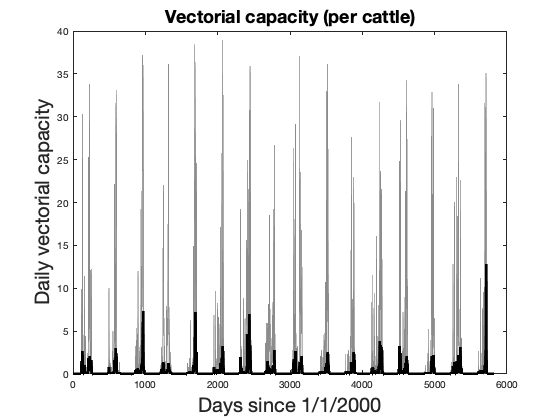

C_low = B_low.*C_hat;
C_median = B_median.*C_hat;
C_high = B_high.*C_hat;
shadedErrorBar(1:length(temp_at_trapsite_NLDS),C_median,[(C_high-C_median)';...
    (C_median - C_low)' ],{'Color','black','LineWidth',3},0.2)
title('Vectorial capacity (per cattle)',"FontSize",18)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('Daily vectorial capacity','FontSize',20);

To emphasise and reiterate, our interpretation is that the uncertainty around the biting rate reflects the uncertainty around the quality of the local habitat for midges. This interpretation stems from the statistical analysis of the trap data; there was strong support for models which included a location-specific random effect. Therefore, different locations which are broadly classed as "farm" environments, and which have commercial livestock herds, will have more or less midge biting depending on unobserved factors. This uncertainty in midge biting propagates to uncertainty in the vectorial capacity.

## BTV reproductive ratio

We consider two species of commerical livestock capable of transmitting BTV, sheep and cattle. The number of secondary infections caused by a single infected cattle is typically greater than the number of secondary infections caused by a single infected sheep. There are two reasons for this, (i) the duration of viraemia is longer for cattle compared to sheep, and (ii) midges are more attracted to biting cattle compared to sheep. As in the main paper and supporting information, we denote the typical number of secondary infections due to a single cattle, resp. sheep, with biting at the *p*th percentile, as $R_p^{( C)}$, resp. $R_p^{(S)}$. Each midge is assumed to be seeking bloodmeals from either cattle or sheep, with the proportion of bites amongst cattle being,

$\phi_C = {N_C \over N_C + \pi_S N_S}$.

Where $N_C$, and, $N_S$, are the numbers of cattle and sheep available for biting and $\pi_S$ is the relative preference for sheep compared to cattle. Solving for the reproductive ratio at biting percentile *p*, denoted $R_p
$ as the leading eigenvalue of the next-generation matrix (see *Methods *and *Supporting Information*) gives

$R_p^2 = \phi_C R_p^{( C)} + (1-\phi_C) R_p^{( S)}$.

As above, we calculate and plot $R_p$ for each day since 1st Jan 2000 at the grid square where the trap locations in the Netherlands were located. We use the same estimate for the relative attractiveness of sheep compared to cattle as in the main paper ($\pi_S = 0.115$). In that grid square contained the trap sites the relative density of cattle was also high compared to sheep ($\phi__C=0.933$). The calculations are performed by the `RForEachLevelOfP` function.

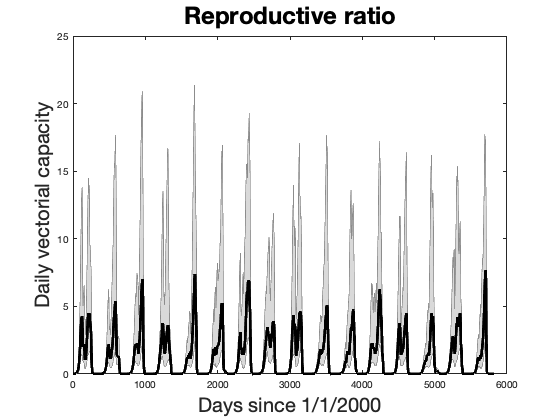

phi_C = 0.933;
phi_S = 1 - phi_C;
R_median = sqrt(RForEachLevelOfP( C_hat,B_median,phi_C,phi_S,0.115,...
    temp_at_trapsite_NLDS,0.5));
R_low = sqrt(RForEachLevelOfP( C_hat,B_median,phi_C,phi_S,0.115,...
    temp_at_trapsite_NLDS,0.05));
R_high = sqrt(RForEachLevelOfP( C_hat,B_median,phi_C,phi_S,0.115,...
    temp_at_trapsite_NLDS,0.95));
shadedErrorBar(1:length(temp_at_trapsite_NLDS),R_median,[(R_high-R_median)';...
    (R_median - R_low)' ],{'Color','black','LineWidth',3},0.2)
title('Reproductive ratio',"FontSize",24)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('Daily vectorial capacity','FontSize',20);

#### Estimating the percentage of herds where BTV can amplify

$R_p$ gives an estimate of the infectious potential of BTV at a herd experiencing *p*th percentile of biting from midges. Since, $R_p$ increases in *p *we can use estimate the proportion of herds having greater reproductive ratio then $R_p$ as *1-p*. The reproductive ratio of an infectious pathogen is an important threshold quantity; if it is less than unity the BTV epizootic cannot amplify over many cycles of transmission. In the main paper, we calculate the quantity $P = \{1-p | R_p = 1\}$ for different days and spatial grid cells, using $P$ as an estimate of the proportion of herds capable of having a BTV outbreak. We calculate this for the Netherlands grid cell which contained the trap locations, and plot below, using the `percherds_Rgthanone` function.

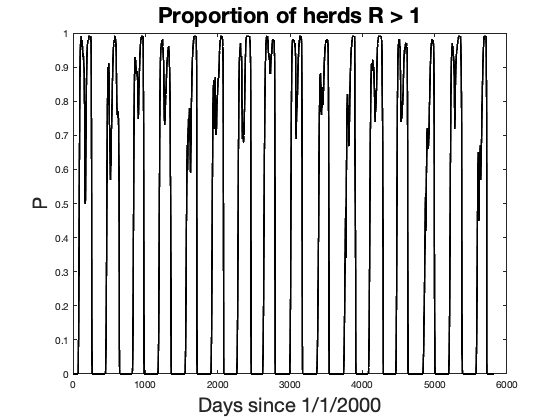

P = percherds_Rgthanone( C_hat,B_median,phi_C,phi_S,0.115,temp_at_trapsite_NLDS);
plot(P,'color','black','LineWidth',2)
title('Proportion of herds R > 1',"FontSize",22)
xlabel('Days since 1/1/2000','FontSize',20)
ylabel('P','FontSize',20);